# Signals & Systems Project - Phase 2

## M.M. Roshani

## 402101855

%% --- SETUP ---
%% NOTE: EEGLAB must be running before we can load .set files!
file_paths = {
    'E:\University\Sophomore\4th semester\Signals & Systems\HW\Project\Whole_Phase_2\Dataset\healthy.set',
    'E:\University\Sophomore\4th semester\Signals & Systems\HW\Project\Whole_Phase_2\Dataset\mci.set',
    'E:\University\Sophomore\4th semester\Signals & Systems\HW\Project\Whole_Phase_2\Dataset\ad.set'
};

group_names = {'Healthy', 'MCI', 'AD'};
odor_names = {'Chocolate', 'Rose'};
odor_codes = [5, 6];

theta_band = [4 8]; 
gamma_band = [30 50];

use_channels = 1:19;  % Channel indices
all_z = struct();      % To store z(t) per group/odor/trial/channel

%% --- PROCESS EACH GROUP AND ODOR ---
for group_idx = 1:length(file_paths)
    fprintf('--- Processing Subject: %s ---\n', group_names{group_idx});
    
    try
        EEG = pop_loadset(file_paths{group_idx});
    catch
        warning('Could not load file: %s. Skipping this group.', file_paths{group_idx});
        continue;
    end
    
    fs = EEG.srate;
    
    % Find trials for each odor
    trial_indices = struct();
    for o = 1:length(odor_codes)
        odor_code = odor_codes(o);
        event_types = [EEG.event.type];
        trial_indices.(odor_names{o}) = find(event_types == odor_code);
    end
    
    % Process each odor
    for o = 1:length(odor_names)
        odor_name = odor_names{o};
        trials = trial_indices.(odor_name);
        
        if isempty(trials)
            warning('No trials found for %s in %s group', odor_name, group_names{group_idx});
            continue;
        end
        
        % Epoch data
        EEG_epoched = pop_epoch(EEG, {}, [-2 5], 'eventindices', trials, 'epochinfo', 'yes');
        nTime = size(EEG_epoched.data, 2);
        nTrials = size(EEG_epoched.data, 3);
        nUsedChannels = length(use_channels);
        
        z_matrix = zeros(nTime, nTrials, nUsedChannels);
        
        for ch_idx = 1:nUsedChannels
            ch = use_channels(ch_idx);
            
            for t = 1:nTrials
                trial_data = EEG_epoched.data(ch, :, t);
                
                % Continuous wavelet transform
                [wt, f] = cwt(trial_data, fs);
                
                theta_idx = f >= theta_band(1) & f <= theta_band(2);
                theta_wt = wt(theta_idx, :);
                theta_phase = angle(mean(theta_wt, 1));  % phase per time point
                
                gamma_idx = f >= gamma_band(1) & f <= gamma_band(2);
                gamma_wt = wt(gamma_idx, :);
                gamma_amp = mean(abs(gamma_wt), 1);      % amplitude per time point
                
                % --- Baseline correction ---
                baseline_idx = find(EEG_epoched.times >= -1 & EEG_epoched.times <= 0);
                baseline_mean_gamma = mean(gamma_amp(baseline_idx));
                if baseline_mean_gamma ~= 0
                    gamma_amp = gamma_amp ./ baseline_mean_gamma;
                end
                
                z_t = gamma_amp .* exp(1i * theta_phase);  % complex signal
                z_matrix(:, t, ch_idx) = z_t.';  % store per trial per channel
            end
        end
        
        % Store
        all_z.(group_names{group_idx}).(odor_name) = z_matrix;
        fprintf('Odor: %s | Trials processed: %d | Channels: %d\n', odor_name, nTrials, nUsedChannels);
    end
end

--- Processing Subject: Healthy ---


pop_loadset(): loading file E:\University\Sophomore\4th semester\Signals & Systems\HW\Project\Whole_Phase_2\Dataset\healthy.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():21 epochs selected
Epoching...
pop_epoch():21 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Odor: Chocolate | Trials processed: 21 | Channels: 19


pop_epoch():22 epochs selected
Epoching...
pop_epoch():22 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Odor: Rose | Trials processed: 22 | Channels: 19


--- Processing Subject: MCI ---


pop_loadset(): loading file E:\University\Sophomore\4th semester\Signals & Systems\HW\Project\Whole_Phase_2\Dataset\mci.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():19 epochs selected
Epoching...
pop_epoch():19 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Odor: Chocolate | Trials processed: 19 | Channels: 19


pop_epoch():21 epochs selected
Epoching...
pop_epoch():21 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Odor: Rose | Trials processed: 21 | Channels: 19


--- Processing Subject: AD ---


pop_loadset(): loading file E:\University\Sophomore\4th semester\Signals & Systems\HW\Project\Whole_Phase_2\Dataset\ad.set ...
eeg_checkset: recomputing the ICA activation matrix ...


pop_epoch():20 epochs selected
Epoching...
pop_epoch():20 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Odor: Chocolate | Trials processed: 20 | Channels: 19


pop_epoch():21 epochs selected
Epoching...
pop_epoch():21 epochs generated
eeg_checkset: recomputing the ICA activation matrix ...
pop_epoch(): checking epochs for data discontinuity


Odor: Rose | Trials processed: 21 | Channels: 19



fprintf('z(t) computation complete.\n');

z(t) computation complete.


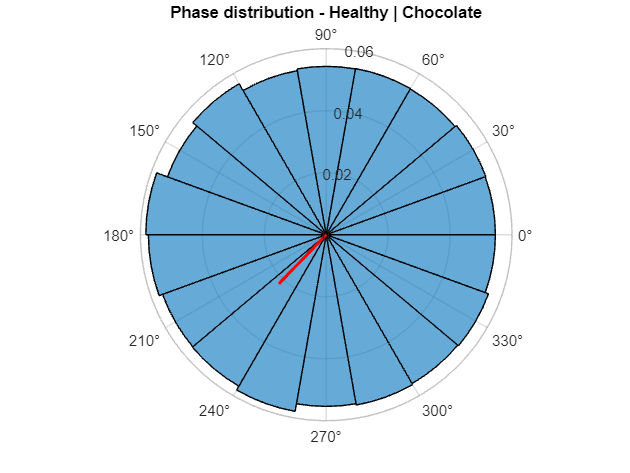

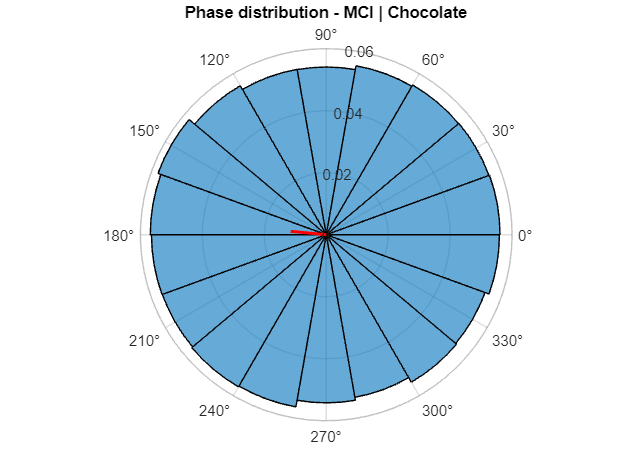

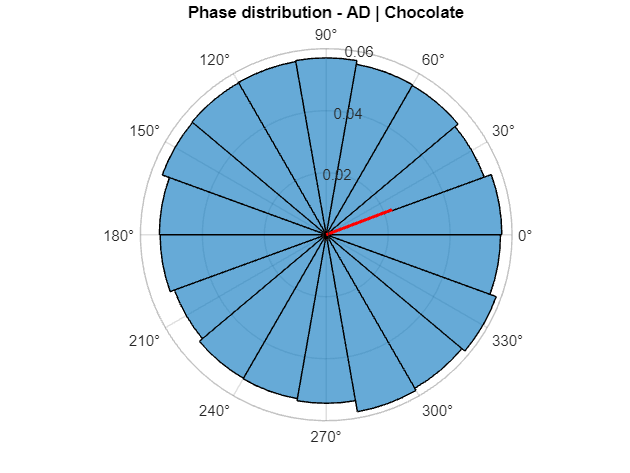

% Polar Histogram Visuals

nBins = 18;

for group_idx = 1:length(group_names)
    group = group_names{group_idx};
    
    for odor_idx = 1:1
        odor = odor_names{odor_idx};
        
        if ~isfield(all_z, group) || ~isfield(all_z.(group), odor)
            continue;
        end
        
        z_matrix = all_z.(group).(odor); % nTime x nTrials x nChannels
        nTrials = size(z_matrix, 2);
        nChannels = size(z_matrix, 3);
        
        % --- Average across channels per trial ---
        z_avg_trials = [];
        for t = 1:nTrials
            z_avg_channels = mean(z_matrix(:, t, :), 3);  % average across channels
            z_avg_trials = [z_avg_trials; z_avg_channels]; % concatenate trials
        end
        
        nPoints = min(40000, length(z_avg_trials));
        idx = round(linspace(1, length(z_avg_trials), nPoints));
        z_sub = z_avg_trials(idx);
        
        theta = angle(z_sub);

        figure;
        polarhistogram(theta, nBins, 'Normalization','probability');
        title(['Phase distribution - ', group, ' | ', odor]);

        % --- Compute MVL ---
        m = mean(exp(1i*theta));  % mean vector
        mvl = abs(m);             % length
        phi = angle(m);           % angle

        % --- Scale MVL ---
        ax = gca;
        rmax = ax.RLim(2);   % maximum radius of histogram
        rlen = mvl * rmax * 30;   % scale MVL length to histogram axis

        % --- Plot MVL line segment ---
        hold on;
        polarplot([phi phi], [0 rlen], 'r-', 'LineWidth', 2);
        hold off;

    end
end

% Overall MVL
all_MVL = struct();

for group_idx = 1:length(group_names)
    group = group_names{group_idx};
    
    for odor_idx = 1:length(odor_names)
        odor = odor_names{odor_idx};
        
        if ~isfield(all_z, group) || ~isfield(all_z.(group), odor)
            continue;
        end
        
        z_matrix = all_z.(group).(odor); % nTime x nTrials x nChannels
        
        % Compute MVL per channel and trial
        MVL_trials_channels = abs(mean(z_matrix, 1)); % 1 x nTrials x nChannels
        
        % Average across channels first
        MVL_per_trial = squeeze(mean(MVL_trials_channels, 3)); % 1 x nTrials
        
        % Then average across trials
        MVL_condition = mean(MVL_per_trial); 
        
        all_MVL.(group).(odor) = MVL_condition;
        
        fprintf('MVL - Group: %s | Odor: %s -> %.5f\n', group, odor, MVL_condition);
    end
end

MVL - Group: Healthy | Odor: Chocolate -> 0.04026
MVL - Group: Healthy | Odor: Rose -> 0.04584
MVL - Group: MCI | Odor: Chocolate -> 0.03777
MVL - Group: MCI | Odor: Rose -> 0.03667
MVL - Group: AD | Odor: Chocolate -> 0.03725
MVL - Group: AD | Odor: Rose -> 0.04141



all_complex_vectors = struct();
for group_idx = 1:length(group_names)
    group = group_names{group_idx};
    for odor_idx = 1:length(odor_names)
        odor = odor_names{odor_idx};
        if ~isfield(all_z, group) || ~isfield(all_z.(group), odor)
            continue;
        end
        nTrials = size(all_z.(group).(odor), 2);
        all_complex_vectors.(group).(odor) = cell(1, nTrials);
        for t = 1:nTrials
            all_complex_vectors.(group).(odor){t} = squeeze(all_z.(group).(odor)(:, t, :));
        end
    end
end

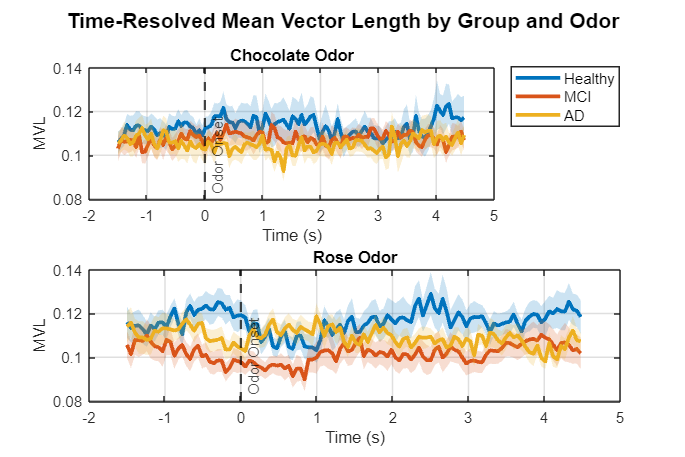

%% --- TIME-RESOLVED MVL ---

window_size_sec = 1;      
overlap_ratio   = 0.95;   
fs              = 250;    

if exist('EEG_epoched', 'var') && isfield(EEG_epoched, 'srate')
    fs = EEG_epoched.srate;
    EEG_epoched_times_sec = EEG_epoched.times / 1000;
else
    n_samples = round(fs * 6); 
    EEG_epoched_times_sec = linspace(-2, 5, n_samples); 
end

window_size_samples = round(window_size_sec * fs);
step_size_samples   = round(window_size_samples * (1 - overlap_ratio));

% --- COLORS & LINE STYLES ---
improved_colors = [0 0.45 0.74; 0.85 0.33 0.1; 0.93 0.69 0.13]; 
line_styles     = {'-', '-'};  

% --- PLOT ---
close all
h_fig = figure('Position',[100 100 900 600]);

for odor_idx = 1:length(odor_names)
    ax(odor_idx) = subplot(length(odor_names),1,odor_idx);
    hold(ax(odor_idx),'on');
    
    legend_handles = [];
    
    for group_idx = 1:length(group_names)
        group = group_names{group_idx};
        odor  = odor_names{odor_idx};
        
        if ~isfield(all_complex_vectors, group) || ~isfield(all_complex_vectors.(group), odor)
            continue
        end
        
        trials_data = all_complex_vectors.(group).(odor); 
        num_trials  = length(trials_data);
        num_time    = size(trials_data{1},1);
        num_channels= size(trials_data{1},2);
        
        n_windows = floor((num_time - window_size_samples)/step_size_samples) + 1;
        time_resolved_mvl = zeros(n_windows,1);
        sem_per_window    = zeros(n_windows,1);
        window_centers    = zeros(n_windows,1);
        
        % --- SLIDING WINDOW LOOP ---
        for w = 1:n_windows
            start_idx = (w-1)*step_size_samples + 1;
            end_idx   = start_idx + window_size_samples - 1;

            mvl_trials_channels = zeros(num_trials, num_channels); 

            for t = 1:num_trials
                window_data = trials_data{t}(start_idx:end_idx,:); 

                % MVL per channel
                mvl_trials_channels(t,:) = abs(mean(window_data,1)); 
            end

            % Average across channels for each trial
            mvl_per_trial = mean(mvl_trials_channels,2); 

            % Then average across trials
            time_resolved_mvl(w) = mean(mvl_per_trial);

            % SEM
            sem_per_window(w) = std(mvl_per_trial)/sqrt(num_trials);

            % Window center
            window_centers(w) = EEG_epoched_times_sec(round((start_idx+end_idx)/2));
        end
        
        h = plot(ax(odor_idx), window_centers, time_resolved_mvl, ...
                 'Color', improved_colors(group_idx,:), ...
                 'LineWidth',2.5, ...
                 'LineStyle', line_styles{odor_idx});
        legend_handles = [legend_handles h(1)];
        
        hold(ax(odor_idx),'on');
        x_fill = [window_centers(:)' fliplr(window_centers(:)')];
        y_fill = [ (time_resolved_mvl(:) + sem_per_window(:))'  fliplr((time_resolved_mvl(:) - sem_per_window(:))') ];

        fill(x_fill, y_fill, improved_colors(group_idx,:), 'FaceAlpha',0.2, 'EdgeColor','none');

    end
    
    title(ax(odor_idx), sprintf('%s Odor', odor_names{odor_idx}),'FontSize',12,'FontWeight','bold');
    xlabel(ax(odor_idx),'Time (s)','FontSize',10);
    ylabel(ax(odor_idx),'MVL','FontSize',10);
    grid(ax(odor_idx),'on'); box(ax(odor_idx),'on'); set(ax(odor_idx),'FontSize',10,'LineWidth',1)
    xline(ax(odor_idx),0,'--k','Odor Onset','LineWidth',1.5,'LabelVerticalAlignment','bottom')
    hold(ax(odor_idx),'off')
end

h_legend = legend(ax(1), legend_handles, group_names, 'Location','bestoutside','FontSize',10);
sgtitle('Time-Resolved Mean Vector Length by Group and Odor','FontSize',14,'FontWeight','bold');

%% --- TIME-RESOLVED MVL with CV Calculation ---

window_size_sec = 1;      
overlap_ratio   = 0.95;   
fs              = 250;    

if exist('EEG_epoched', 'var') && isfield(EEG_epoched, 'srate')
    fs = EEG_epoched.srate;
    EEG_epoched_times_sec = EEG_epoched.times / 1000;
else
    n_samples = round(fs * 6); 
    EEG_epoched_times_sec = linspace(-2, 5, n_samples); 
end

window_size_samples = round(window_size_sec * fs);
step_size_samples   = round(window_size_samples * (1 - overlap_ratio));

cv_results = struct();

for odor_idx = 1:length(odor_names)
    for group_idx = 1:length(group_names)
        group = group_names{group_idx};
        odor  = odor_names{odor_idx};

        if ~isfield(all_complex_vectors, group) || ~isfield(all_complex_vectors.(group), odor)
            continue
        end

        trials_data = all_complex_vectors.(group).(odor); 
        num_trials  = length(trials_data);
        num_time    = size(trials_data{1},1);
        num_channels= size(trials_data{1},2);

        n_windows = floor((num_time - window_size_samples)/step_size_samples) + 1;
        mvl_per_window = zeros(n_windows,1);

        % --- SLIDING WINDOW LOOP ---
        for w = 1:n_windows
            start_idx = (w-1)*step_size_samples + 1;
            end_idx   = start_idx + window_size_samples - 1;

            mvl_trials_channels = zeros(num_trials, num_channels); 

            for t = 1:num_trials
                window_data = trials_data{t}(start_idx:end_idx,:); 
                % MVL per channel
                mvl_trials_channels(t,:) = abs(mean(window_data,1)); 
            end

            % Average across channels per trial
            mvl_per_trial = mean(mvl_trials_channels,2);

            % Mean across trials = MVL in this window
            mvl_per_window(w) = mean(mvl_per_trial);
        end

        % --- CV per odor × group ---
        mvl_mean = mean(mvl_per_window);
        mvl_std  = std(mvl_per_window);
        cv_value = mvl_std / mvl_mean;

        cv_results.(group).(odor) = cv_value;

        % Print
        fprintf('Odor: %s | Group: %s | MVL CV = %.4f\n', odor, group, cv_value);
    end
end

Odor: Chocolate | Group: Healthy | MVL CV = 0.0347
Odor: Chocolate | Group: MCI | MVL CV = 0.0236
Odor: Chocolate | Group: AD | MVL CV = 0.0319
Odor: Rose | Group: Healthy | MVL CV = 0.0462
Odor: Rose | Group: MCI | MVL CV = 0.0421
Odor: Rose | Group: AD | MVL CV = 0.0374



disp('--- Total MVL CV per odor × condition computed. ---')

--- Total MVL CV per odor × condition computed. ---


% --- MODULATION INDEX (MI) USING z(t) PER CHANNEL --- 
n_bins = 18;
bin_edges = linspace(-pi, pi, n_bins+1);
mi_results = struct();

fprintf('\n--- Calculating MI per channel first, then average ---\n');


--- Calculating MI per channel first, then average ---



for group_idx = 1:length(group_names)
    group = group_names{group_idx};
    
    for odor_idx = 1:length(odor_names)
        odor = odor_names{odor_idx};
        
        if ~isfield(all_complex_vectors, group) || ~isfield(all_complex_vectors.(group), odor)
            warning('Data not found for %s - %s. Skipping.', group, odor);
            continue;
        end
        
        trials_data = all_complex_vectors.(group).(odor); % cell array per trial
        nTrials = length(trials_data);
        nChannels = size(trials_data{1},2);
        
        mi_trials_channels = zeros(nTrials, nChannels);
        
        for t = 1:nTrials
            z_trial = trials_data{t}; % time * channels
            
            for ch = 1:nChannels
                z_ch = z_trial(:,ch); % single channel
                theta_phase = angle(z_ch);
                gamma_amp = abs(z_ch);
                
                trial_dist = zeros(n_bins,1);
                for b = 1:n_bins
                    if b < n_bins
                        idx = find(theta_phase >= bin_edges(b) & theta_phase < bin_edges(b+1));
                    else
                        idx = find(theta_phase >= bin_edges(b) & theta_phase <= bin_edges(b+1));
                    end
                    if ~isempty(idx)
                        trial_dist(b) = mean(gamma_amp(idx));
                    end
                end
                
                sum_amp = sum(trial_dist);
                if sum_amp == 0
                    mi_trials_channels(t,ch) = NaN;
                else
                    norm_dist = trial_dist / sum_amp;
                    uniform_dist = ones(n_bins,1)/n_bins;
                    mi_trials_channels(t,ch) = sum(norm_dist .* log(norm_dist ./ (uniform_dist + eps))) / log(n_bins);
                end
            end
        end
        
        % Average across channels per trial
        mi_per_trial = mean(mi_trials_channels,2,'omitnan');
        
        % Average across trials
        mi_results.(group).(odor).mi = mean(mi_per_trial,'omitnan');
        mi_results.(group).(odor).mi_per_trial = mi_per_trial;
        
        fprintf('  MI for %s - %s: %.8f\n', group, odor, mi_results.(group).(odor).mi);
    end
end

  MI for Healthy - Chocolate: 0.00043927
  MI for Healthy - Rose: 0.00045104
  MI for MCI - Chocolate: 0.00038019
  MI for MCI - Rose: 0.00038210
  MI for AD - Chocolate: 0.00043252
  MI for AD - Rose: 0.00045227


%% --- TIME-RESOLVED MI ---

n_bins = 18;
bin_edges = linspace(-pi, pi, n_bins+1);

window_size_sec = 1;
overlap_ratio = 0.95;
fs = EEG_epoched.srate;

window_size_samples = round(window_size_sec * fs);
step_size_samples = round(window_size_samples * (1 - overlap_ratio));

mi_time_resolved = struct();
mi_sem_time_resolved = struct();
window_centers = struct();

for group_idx = 1:length(group_names)
    group = group_names{group_idx};
    
    for odor_idx = 1:length(odor_names)
        odor = odor_names{odor_idx};
        
        if ~isfield(all_complex_vectors, group) || ~isfield(all_complex_vectors.(group), odor)
            warning('Data not found for %s - %s. Skipping.', group, odor);
            continue;
        end
        
        trials_data = all_complex_vectors.(group).(odor); % cell array: trial x (time x channels)
        nTrials = length(trials_data);
        n_time = size(trials_data{1},1);
        n_channels = size(trials_data{1},2);
        
        n_windows = floor((n_time - window_size_samples)/step_size_samples) + 1;
        win_mi_mean = zeros(n_windows,1);
        win_mi_sem = zeros(n_windows,1);
        win_center_times = zeros(n_windows,1);
        
        for w = 1:n_windows
            start_sample = (w-1)*step_size_samples + 1;
            end_sample = start_sample + window_size_samples - 1;
            
            mi_per_trial = zeros(nTrials,1);
            
            for t = 1:nTrials
                z_trial = trials_data{t}(start_sample:end_sample,:); % window x channels
                mi_per_ch = zeros(n_channels,1);
                
                for ch = 1:n_channels
                    z_ch = z_trial(:,ch);
                    theta_phase = angle(z_ch);
                    gamma_amp = abs(z_ch);
                    
                    trial_dist = zeros(n_bins,1);
                    for b = 1:n_bins
                        if b < n_bins
                            idx = theta_phase >= bin_edges(b) & theta_phase < bin_edges(b+1);
                        else
                            idx = theta_phase >= bin_edges(b) & theta_phase <= bin_edges(b+1);
                        end
                        if any(idx)
                            trial_dist(b) = mean(gamma_amp(idx));
                        end
                    end
                    
                    sum_amp = sum(trial_dist);
                    if sum_amp == 0
                        mi_per_ch(ch) = NaN;
                    else
                        norm_dist = trial_dist / sum_amp;
                        uniform_dist = ones(n_bins,1)/n_bins;
                        mi_per_ch(ch) = sum(norm_dist .* log(norm_dist ./ (uniform_dist + eps))) / log(n_bins);
                    end
                end
                
                % Average MI across channels for this trial
                mi_per_trial(t) = mean(mi_per_ch, 'omitnan');
            end
            
            % Average MI across trials for this window
            win_mi_mean(w) = mean(mi_per_trial, 'omitnan');
            
            % SEM across trials
            win_mi_sem(w) = std(mi_per_trial, 'omitnan') / sqrt(sum(~isnan(mi_per_trial)));
            
            % Window center in seconds
            win_center_times(w) = ((start_sample + end_sample)/2)/fs;
        end
        
        mi_time_resolved.(group).(odor) = win_mi_mean;
        mi_sem_time_resolved.(group).(odor) = win_mi_sem;
        window_centers.(group).(odor) = win_center_times;
    end
end

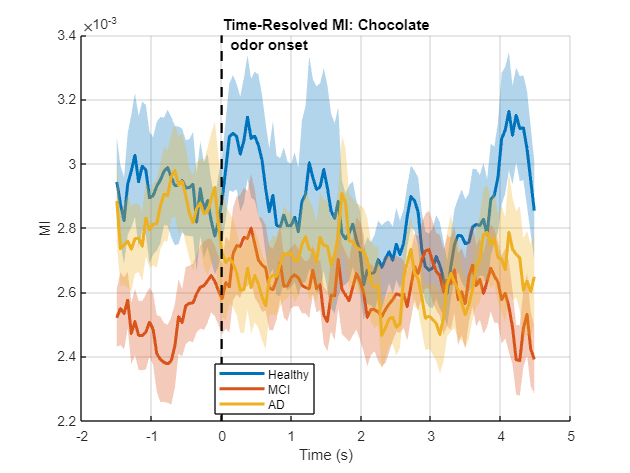

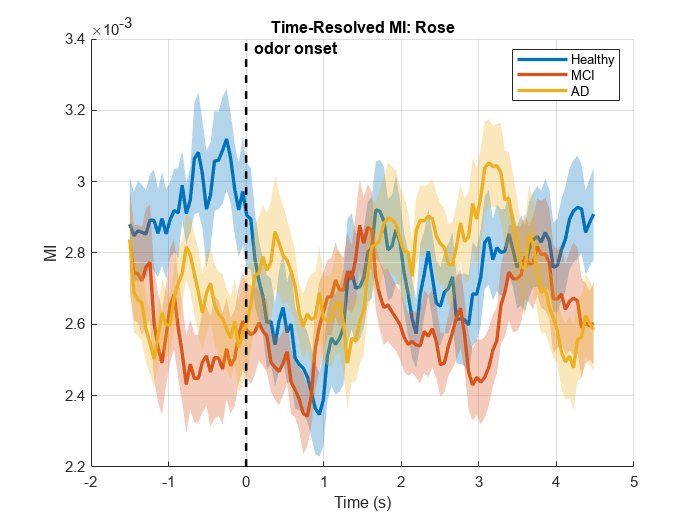

%% --- Plot Time-Resolved MI with SEM (one figure per odor) ---
colors = [
    0 0.45 0.74;   % blue
    0.85 0.33 0.1; % red
    0.93 0.69 0.13;% yellow
];

for odor_idx = 1:length(odor_names)
    odor = odor_names{odor_idx};
    figure; hold on;
    
    legend_handles = []; 
    legend_entries = {};
    
    for group_idx = 1:length(group_names)
        group = group_names{group_idx};
        
        if ~isfield(mi_time_resolved, group) || ~isfield(mi_time_resolved.(group), odor)
            continue;
        end
        
        mi_values = mi_time_resolved.(group).(odor);
        mi_sem    = mi_sem_time_resolved.(group).(odor);
        time_axis = window_centers.(group).(odor);
        
        % Ensure row vectors
        mi_values = mi_values(:)'; 
        mi_sem    = mi_sem(:)'; 
        time_axis = time_axis(:)';
        
        % Shift time axis so that it starts at -2
        time_axis = time_axis - time_axis(1) - 1.5;
        
        % Shaded error bar (SEM)
        fill([time_axis, fliplr(time_axis)], ...
             [mi_values + mi_sem, fliplr(mi_values - mi_sem)], ...
             colors(group_idx,:), 'FaceAlpha',0.3, 'EdgeColor','none');
        
        % Main line plot, keep handle for legend
        h = plot(time_axis, mi_values, 'Color', colors(group_idx,:), 'LineWidth',2);
        
        legend_handles(end+1) = h;
        legend_entries{end+1} = group;
    end
    
    xlim([-2 5]);
    % Mark odor onset at t=0
    yl = ylim;
    plot([0 0], yl, 'k--', 'LineWidth', 1.5);
    text(0, yl(2), '  odor onset', 'VerticalAlignment','top', 'FontSize',10, 'FontWeight','bold');
    
    xlabel('Time (s)');
    ylabel('MI');
    title(sprintf('Time-Resolved MI: %s', odor), 'Interpreter', 'none');
    legend(legend_handles, legend_entries, 'Location', 'best');
    grid on;
    hold off;
end

%% --- Plot Time-Resolved MVL (per Group-Odor-Channel) ---

% --- PARAMETERS ---
window_size_sec = 1;
overlap_ratio   = 0.95;
fs = EEG_epoched.srate; % Use actual sampling rate from EEG data
EEG_epoched_times_sec = EEG_epoched.times / 1000; % Convert milliseconds to seconds

% Calculate window and step sizes in samples
window_size_samples = round(window_size_sec * fs);
step_size_samples   = round(window_size_samples * (1 - overlap_ratio));


%% --- Data Preparation: Calculate Time-Resolved MVL per Channel ---

mi_time_resolved = struct();
window_centers = struct();

for group_idx = 1:length(group_names)
    group = group_names{group_idx};
    
    for odor_idx = 1:length(odor_names)
        odor = odor_names{odor_idx};
        
        % Check if data exists for the current group-odor combination
        if ~isfield(all_z, group) || ~isfield(all_z.(group), odor)
            fprintf('Skipping MI calculation for Group: %s | Odor: %s (No data in all_z).\n', group, odor);
            continue;
        end
        
        z_data_current_condition = all_z.(group).(odor); % Get z-transformed data: time x trials x channels
        
        num_time_points = size(z_data_current_condition, 1);
        num_trials = size(z_data_current_condition, 2);
        num_channels_in_data = size(z_data_current_condition, 3); % Total channels available in the data
        
        n_windows = floor((num_time_points - window_size_samples) / step_size_samples) + 1;
        
        current_condition_mi_channels = zeros(n_windows, num_channels_in_data);
        current_window_centers_vec = zeros(n_windows, 1);
        
        % --- SLIDING WINDOW LOOP ---
        for w = 1:n_windows
            start_idx = (w - 1) * step_size_samples + 1;
            end_idx   = start_idx + window_size_samples - 1;
            
            % Result: time_window x nTrials x nChannels
            window_data = z_data_current_condition(start_idx:end_idx, :, :);
            
            % Compute MI for each channel within this window
            for ch_idx_data = 1:num_channels_in_data % Loop through ALL channels in the data
                % Result: time_window x nTrials
                data_for_current_channel = squeeze(window_data(:, :, ch_idx_data));
                
                % Compute Mean Vector Length (MVL) for each trial for the current channel.
                mi_per_trial_channel = abs(mean(data_for_current_channel, 1)); % 1 x nTrials
                
                % Average these MVL values across trials for the current channel and window
                current_condition_mi_channels(w, ch_idx_data) = mean(mi_per_trial_channel);
            end
            
            % Calculate the center time point for the current window
            current_window_centers_vec(w) = EEG_epoched_times_sec(round((start_idx + end_idx) / 2));
        end
        

        mi_time_resolved.(group).(odor) = current_condition_mi_channels;
        window_centers.(group).(odor) = current_window_centers_vec;
        
        fprintf('Calculated MI for Group: %s | Odor: %s. Data dimensions: %s\n', ...
            group, odor, mat2str(size(current_condition_mi_channels)));
    end
end

Calculated MI for Group: Healthy | Odor: Chocolate. Data dimensions: [116 19]
Calculated MI for Group: Healthy | Odor: Rose. Data dimensions: [116 19]
Calculated MI for Group: MCI | Odor: Chocolate. Data dimensions: [116 19]
Calculated MI for Group: MCI | Odor: Rose. Data dimensions: [116 19]
Calculated MI for Group: AD | Odor: Chocolate. Data dimensions: [116 19]
Calculated MI for Group: AD | Odor: Rose. Data dimensions: [116 19]



%% --- Plot Time-Resolved MVL (per Group-Odor-Channel) ---


channels_to_plot = [1 5]; % channel numbers to be plotted

% --- PLOT SETUP ---
close all
h_fig = figure('Position',[100 100 1400 900]);
set(h_fig, 'color', 'w');

plot_counter = 0;
num_groups = length(group_names); % Total number of groups (e.g., Healthy, MCI, AD)
num_odors = length(odor_names);   % Total number of odors (e.g., Chocolate, Mint)
total_plots = num_groups * num_odors;


for group_idx = 1:num_groups
    group = group_names{group_idx};

    for odor_idx = 1:length(odor_names)
        odor  = odor_names{odor_idx};

        plot_counter = plot_counter + 1;
        
        ax(plot_counter) = subplot(num_groups, num_odors, plot_counter);
        hold(ax(plot_counter),'on');

        
        channel_legends = {};
        
        % --- Data Existence Check ---

        if ~isfield(mi_time_resolved, group) || ~isfield(mi_time_resolved.(group), odor) || ...
           ~isfield(window_centers, group) || ~isfield(window_centers.(group), odor)
            title(ax(plot_counter), sprintf('%s - %s Odor (No Data)', group, odor),'FontSize',12,'FontWeight','bold');
            xlabel(ax(plot_counter),'Time (s)','FontSize',10);
            ylabel(ax(plot_counter),'MI','FontSize',10);
            grid(ax(plot_counter),'on'); box(ax(plot_counter),'on'); set(ax(plot_counter),'FontSize',10,'LineWidth',1);
            hold(ax(plot_counter),'off');
            continue;
        end

        % Retrieve MVL values and time axis for the current group-odor condition
        mi_values_all_channels = mi_time_resolved.(group).(odor);
        time_axis_orig         = window_centers.(group).(odor);
        

        disp(['Size of MI data for plotting for ', group, ' - ', odor, ': ', mat2str(size(mi_values_all_channels))]);

        total_channels_in_data = size(mi_values_all_channels, 2); 
        
        time_axis_orig = time_axis_orig(:)';
        
        time_axis = time_axis_orig - time_axis_orig(1) - 1.5; 
        
        % Define a colormap for distinct channel colors based on the number of SELECTED channels
        channel_colors = lines(max(1, length(channels_to_plot))); 

        % --- PLOT MVL for each SELECTED channel within the current subplot ---
        for k = 1:length(channels_to_plot)
            current_channel_idx = channels_to_plot(k);

            if current_channel_idx > total_channels_in_data || current_channel_idx < 1
                fprintf('Warning: Channel %d for Group: %s, Odor: %s is out of bounds for data with %d channels. Skipping.\n', ...
                    current_channel_idx, group, odor, total_channels_in_data);
                continue; % Skip to the next selected channel
            end

            % Extract MVL values for the current SELECTED channel
            mi_current_channel = mi_values_all_channels(:, current_channel_idx)';
            
            h_line = plot(time_axis, mi_current_channel, ...
                          'Color', channel_colors(k,:), ...
                          'LineWidth', 2);
            
            % Add legend entry for the current channel.
            if exist('EEG_epoched', 'var') && isfield(EEG_epoched, 'chanlocs') && current_channel_idx <= length(EEG_epoched.chanlocs)
                channel_legends{end+1} = EEG_epoched.chanlocs(current_channel_idx).labels; % Use current_channel_idx here!
            else
                channel_legends{end+1} = sprintf('Channel %d', current_channel_idx); % Use current_channel_idx here!
            end
        end
        
        % Set the title for the current subplot
        title(ax(plot_counter), sprintf('%s - %s Odor', group, odor),'FontSize',12,'FontWeight','bold');
        
        % Set common X and Y limits to ensure consistency across subplots,
        xlim(ax(plot_counter), [-2 5]); % Example range for time
        
        if ~isempty(channels_to_plot) && ~isempty(mi_values_all_channels)
            % Extract data for only the selected channels
            selected_channels_data = mi_values_all_channels(:, channels_to_plot);
            
            if ~isempty(selected_channels_data)
                min_mi = min(selected_channels_data(:));
                max_mi = max(selected_channels_data(:));
                ylim(ax(plot_counter), [min_mi - abs(min_mi)*0.1, max_mi + abs(max_mi)*0.1]); 
            else
                ylim(ax(plot_counter), [0 1]);
            end
        else
            ylim(ax(plot_counter), [0 1]);
        end
        
        % Mark odor onset at t=0
        yl = ylim(ax(plot_counter)); % Get current Y limits of the subplot
        plot(ax(plot_counter), [0 0], yl, 'k--', 'LineWidth', 1.5, 'HandleVisibility','off');
        text(ax(plot_counter), 0, yl(2), '  Odor Onset', 'VerticalAlignment','top', 'FontSize',10, 'FontWeight','bold'); % '  ' for slight offset

        % Only add Y-axis label to the subplots in the first column to avoid clutter
        if mod(plot_counter-1, num_odors) == 0 
            ylabel(ax(plot_counter),'MI','FontSize',10);
        else
            set(ax(plot_counter), 'YTickLabel', []);
        end
        
        % Only add X-axis label to the subplots in the bottom row to avoid clutter
        if plot_counter > total_plots - num_odors
             xlabel(ax(plot_counter),'Time (s)','FontSize',10);
        else
            set(ax(plot_counter), 'XTickLabel', []); % Hide X-axis labels for other rows
        end

        % Add grid, box, and set font size/line width for axes aesthetics
        grid(ax(plot_counter),'on'); 
        box(ax(plot_counter),'on'); 
        set(ax(plot_counter),'FontSize',10,'LineWidth',1);
        
        hold(ax(plot_counter),'off');

        % Add a legend specific to this subplot, showing which curve corresponds to which channel
        if ~isempty(channel_legends)
            legend(ax(plot_counter), channel_legends, 'Location','best','FontSize',9);
        end
    end
end

Size of MI data for plotting for Healthy - Chocolate: [116 19]
Size of MI data for plotting for Healthy - Rose: [116 19]
Size of MI data for plotting for MCI - Chocolate: [116 19]
Size of MI data for plotting for MCI - Rose: [116 19]
Size of MI data for plotting for AD - Chocolate: [116 19]
Size of MI data for plotting for AD - Rose: [116 19]


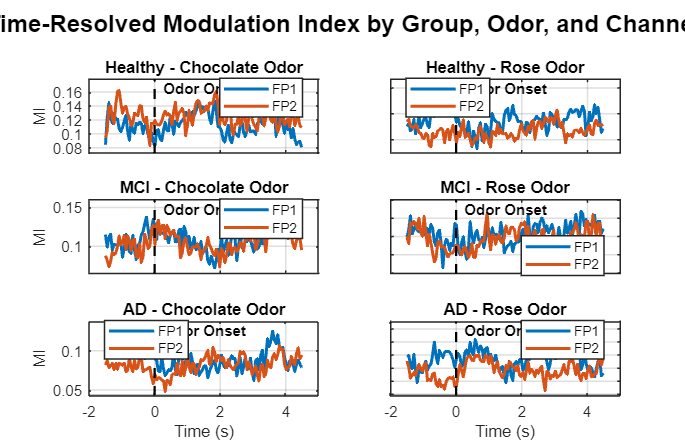


sgtitle('Time-Resolved Modulation Index by Group, Odor, and Channel','FontSize',16,'FontWeight','bold');